# SEIR Model Simulation

Copyright 2022 The MathWorks, Inc

This is a simple **SEIR** model of disease spread, implemented in MATLAB. This approach is widely used to analyze infection data during the different stages of an epidemic outbreak. The population is divided into Susceptible (S), Exposed (E), Infectious (I), and Recovered (R) individuals.

## The Model Overview

The equations that make up the SEIR model are described by 4 ordinary differential equations as follows:

## Model Simulation

**Model Parameters**

Play around with the parameters using the sliders and see the effect on the plot.

clc; clear; close all;
beta   = 0.90  ;                     % Transmission Rate
gamma  = 0.071 ;                     % Recovery Rate
lambda = 0.2   ;                     % Rate at which exposed individuals become Infectious
N = 8500000;                         % Total population 
I0 = 20;                             % Initial number of infected individuals
E0 = 0;                              % Initial number of exposed individuals
S0 = N-I0-E0;                        % Initial number of susceptible individuals
T = 365;                             % Period of 365 days
R0=beta/gamma;                       % Reproduction number

**Solve the ODE using **[ode45](https://www.mathworks.com/help/matlab/ref/ode45.html).

y0 = [S0; E0; I0; R0];                % Initial conditions
tspan = [0 T];                        % Interval of Integration
[t,y] = ode45(@(t,y) seir_model(t,y,beta,lambda,gamma,N),tspan,y0);

For more info see the [Anonymous functions documentation](http://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html).

**Plots that show the results**

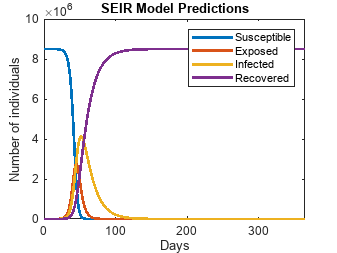

plot(t,y,'LineWidth',2);
xlabel('Days'); 
ylabel('Number of individuals');
legend('Susceptible','Exposed','Infected','Recovered');
title('SEIR Model Predictions');
xlim([0 T]);

For more info see the [plot documentation](https://www.mathworks.com/help/matlab/ref/plot.html).

The recovary rate refers to the number of individuals that no longer have the disease. This happens through becoming healthy or dying. For the mortality rate, we simply need to break the recovery rate into two parts: healthy recovery and death. For death, we take the mortality rate of the disease and multiply it by the recovery rate. For the healthy recovery rate, we take the difference from the morality rate and remove it from the normal recovery rate.

D = 15;                     % Death rate as a percent
yD = .01*D*y(:,4);          % Values for each day
plot(t,yD, 'LineWidth', 2); % New graph
legend('Mortality');
xlabel('Days'); 
ylabel('Number of individuals');
title('Mortality Rate');
xlim([0 T]);

The new graph, SEIHM, with H refering to the healthy rate and M refering to the mortality rate, is this:

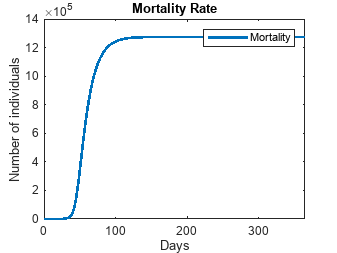

hold off

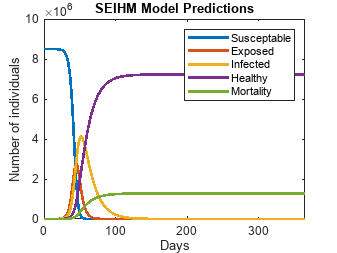

yH = (1-(D*.01))*y(:,4);         % Healthy rate
plot(t,y(:, 1:3),'LineWidth',2); % New graph
xlim([0 T]);                     % Cuts off graph
hold on
plot(t,yH,'LineWidth',2);
plot(t,yD,'LineWidth',2);
xlabel('Days'); 
ylabel('Number of individuals');
legend('Susceptable', 'Exposed','Infected','Healthy','Mortality');
title('SEIHM Model Predictions');

To find the total deaths from the disease, we take the final time point of the graph. This will often be more useful than the graph because most dieseases have low mortality rates which are hard to visualize on the overall graph.

Dead = yD(length(yD));
fprintf('The total deaths from the disease after one year are %.0f', Dead)

The total deaths from the disease after one year are 1274998

**Function **`seir_model`** that calculates the model evolution over a time period T.**

function dydt = seir_model(t,y,beta,lambda,gamma,N)
  S = y(1);
  E = y(2);
  I = y(3);
  % Equations of the model described above
  dS = (-beta*S*I/N) ;
  dE = (beta*I*S/N - lambda*E) ;
  dI = (lambda*E - gamma*I);
  dR = (gamma*I);
  dydt = [dS;dE;dI;dR];
end

## Further Evaluation

The three critical parameters in the model are beta, lambda and gamma.

Note that we have left several features unmodeled, for example: 

- Immunity loss rate, where recovered individuals can get infected again.

- Some exposed individuals in "E" might move directly to the "R" category;

- Some infected individuals in category "I" might not gain perfect immunity and so may move back to susceptible category "S." 

Despite these limitations, this basic SEIR model can provide some useful insights on the disease evolution.